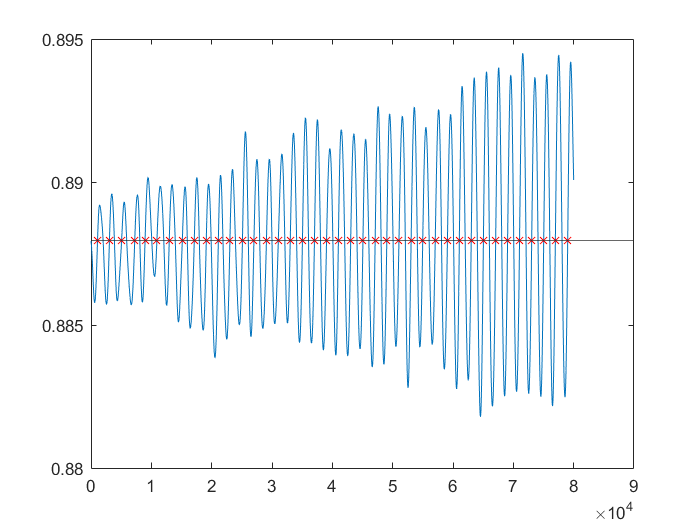

% function [I_spike_phase, II_spike_phase, III_spike_phase, I_spike, II_spike, III_spike] = spike_phase(stimulus, raster_data, fs, start_stim, stop_stim, stim_type, freq)

resp = P(1).raster(:,start_stim+2*fs:stop_stim);
stim = P(1).antennal_movement(:,start_stim+2*fs:stop_stim);
mean_pos = mean(stim(1,:));
freq = linspace(1,300,length(stim));

locs = [];
zc = nan([1,length(stim)]);
for j = 2:length(stim)
    if (stim(1,j-1)<=mean_pos && stim(1,j)>=mean_pos && stim(1,j+1)>mean_pos)
        zc(j) = 1;
    end
end
locs = find(zc==1);

% figure;
% A1 =  subplot(2,1,1); 
figure;
plot(stim(1,:)); hold on; plot(locs, stim(1, locs), 'rx'); yline(mean_pos); hold off;


stim_clips = [];
resp_clips = [];
I_spike_phase = [];
II_spike_phase = [];
III_spike_phase = [];
I_spike = [];
II_spike = [];
III_spike = [];

spike_time_sd = [];


I = 1; II = 1; III=1;
for k= 2:length(locs)
    stim_clips = stim(1, locs(k-1):locs(k));
    resp_clips = resp(:, locs(k-1):locs(k));
    
    [row_ind,col_ind] = find(resp_clips == 1);
    
    
    [C, ia, ic] = unique(row_ind, 'stable');
    ind = col_ind(ia);
    
%         figure;
%         plot(stim_clips); hold on; plot(ind, stim_clips(ind), 'rx');
    
    if length(col_ind)>=1
        %             I_spike_phase(I) = get_spike_phase(ind(1), fs, stim_period(ind(1)));
        %             I_spike_phase(I) = get_spike_phase(ind(1), fs, stim_period(k-1));
        I_spike_time = ind/fs;
        if length(ind) >=3
            spike_time_sd(I) = std(I_spike_time);
            %             I_spike(I) = freq(ind(1)+locs(k-1));%stim_freq(k-1);
            I_spike(I) = max(stim_clips) - min(stim_clips);
            I=I+1;
        end
    end
    
    
    
    %     elseif stim_type == "amp"
    %
    %         stim_period = 1/freq;
    % %         stim_freq = 1 ./ (diff(locs) / fs);
    % %         stim_period = 1./stim_freq;
    %
    %         if length(ind)>=1
    %             I_spike_phase(I) = get_spike_phase(ind(1), fs, stim_period);
    %             I_spike(I) = max(stim_clips) - min(stim_clips);
    %             I=I+1;
    %         end
    %
    %
    %     end
end

figure
% scatter(I_spike, spike_time_sd, 20, "filled")
[f, gof] = fit(I_spike', spike_time_sd', 'poly1')

f =      Linear model Poly1:
     f(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =    -0.07298  (-0.2037, 0.05778)
       p2 =    0.003335  (0.002278, 0.004393)

gof = struct with fields:
           sse: 4.3113e-05
       rsquare: 0.0334
           dfe: 37
    adjrsquare: 0.0073
          rmse: 0.0011


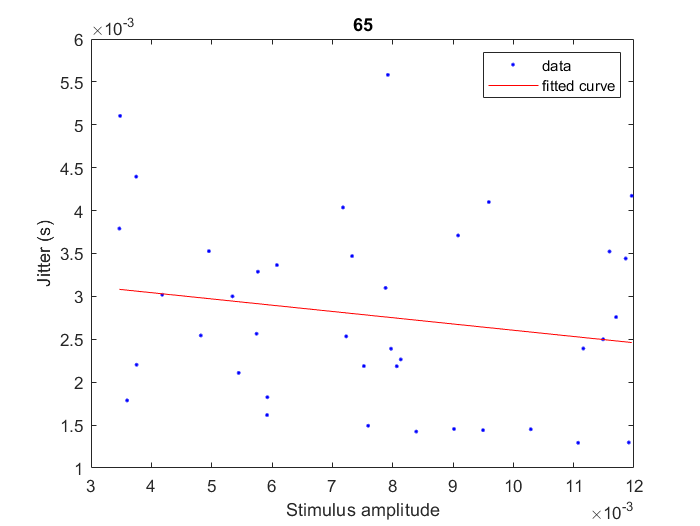

plot(f, I_spike, spike_time_sd)
ylabel('Jitter (s)');
xlabel('Stimulus amplitude')
title('65')